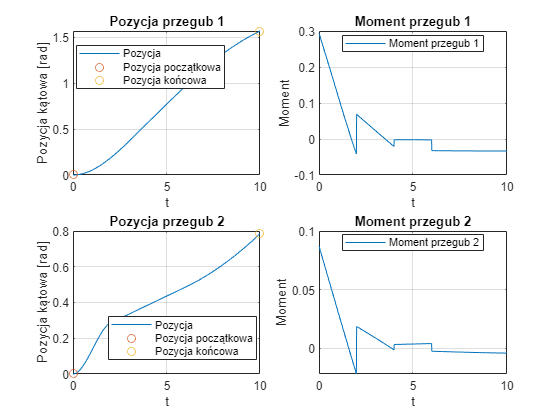

clear all
syms a_0 a_1 a_2 a_3 b_0 b_1 c_0 c_1 c_2 c_3
syms q_p q_k v
syms t_a t_c t_k t_b
syms dq_k dq_p


t_c = t_k-t_b;

A = a_0 - q_p;

B = a_1 - dq_p;

C = a_0 + a_1*t_a + a_2*(t_a)^2 + a_3*(t_a)^3 - b_0 - b_1*t_a;

D = a_1 + 2*a_2*t_a + 3*a_3*(t_a)^2 - b_1;

E = a_1 + 2*a_2*t_a + 3*a_3*(t_a)^2 - c_1 - 2*c_2*t_c - 3*c_3*(t_c)^2;

F = b_1 - v;

G = b_0 + b_1*t_c - c_0 - c_1*t_c - c_2*(t_c)^2 - c_3*(t_c)^3;
 
H = b_1 - c_1 - 2*c_2*t_c - 3*c_3*(t_c)^2;

I = c_0 + c_1*t_k + c_2*(t_k)^2 + c_3*(t_k)^3 -q_k;

J = c_1 + 2*c_2*t_k + 3*c_3*(t_k)^2 - dq_k;

[Z] = solve(A==0, B==0, C==0, D==0, E==0, F==0, G==0, H==0, I==0, J==0 ,a_0, a_1, a_2, a_3, b_0, b_1, c_0, c_1, c_2, c_3);

solved = Z;
q_p_1 = 0;          % pozycja początkowa przegubu nr 1 [rad]
dq_p_1 = 0.0;       % prędkość początkowa przegubu nr 1 [rad]
q_k_1 = 1/2 * pi;   % pozycja końcowa przegubu nr 1 [rad/s]
dq_k_1 = 0.1;       % prędkość końcowa przegubu nr 1 [rad/s]
Tk_1 = 10;          % Czas trwania ruchu przegubu [s]
Ta_1 = 4;           % Czas trwania fazy przyspieszania [s]
Tb_1 = 4;           % Czas trwania fazy hamowania [s]
dt_1 = 0.01;        % Krok czasowy [s]    
V_1 = 0.2;          % Prędkość przegubu w fazie drugiej [rad/s]
[q_1,dq_1,ddq_1, t_1] = Trajectory_Generation(solved, q_p_1, dq_p_1,...
q_k_1, dq_k_1, Tk_1, Ta_1, Tb_1, dt_1, V_1);

q_1 = double(q_1);
dq_1 = double(dq_1);
ddq_1 = double(ddq_1);

q_p_2 = 0;          % pozycja początkowa przegubu nr 1 [rad]
dq_p_2 = 0.0;       % prędkość początkowa przegubu nr 1 [rad]
q_k_2 = 1/4 * pi;   % pozycja końcowa przegubu nr 1 [rad/s]
dq_k_2 = 0.1;       % prędkość końcowa przegubu nr 1 [rad/s]
Tk_2 = 10;          % Czas trwania ruchu przegubu [s]
Ta_2 = 2;           % Czas trwania fazy przyspieszania [s]
Tb_2 = 4;           % Czas trwania fazy hamowania [s]
dt_2 = 0.01;        % Krok czasowy [s]   
V_2 = 0.05;          % Prędkość przegubu w fazie drugiej [rad/s]
[q_2,dq_2,ddq_2, t_2] = Trajectory_Generation(solved, q_p_2, dq_p_2, ...
    q_k_2, dq_k_2, Tk_2, Ta_2, Tb_2, dt_2, V_2);

q_2 = double(q_2);
dq_2 = double(dq_2);
ddq_2 = double(ddq_2);

m1 = 2.5;
m2 = 1.5;
L1 = 0.6;
L2 = 0.5;

[u] = dynamics_model(q_1, q_2, dq_1, dq_2, ddq_1, ddq_2, m1, m2, L1, L2);
u_1 = u(1, :);
u_2 = u(2, :);

figure;
subplot(2, 2, 1);
plot(t_1, q_1, t_1(1), q_p_1, 'o', Tk_1, q_k_1, 'o')
legend('Pozycja', 'Pozycja początkowa', 'Pozycja końcowa', "Location","best")
title('Pozycja przegub 1')
xlabel('t')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(2, 2, 2);
plot(t_1, u_1)
legend('Moment przegub 1', "Location","best")
title('Moment przegub 1')
xlabel('t')
ylabel('Moment')
grid on
axis auto

subplot(2, 2, 3);
plot(t_2, q_2, t_2(1), q_p_2, 'o', Tk_2, q_k_2, 'o')
legend('Pozycja', 'Pozycja początkowa', 'Pozycja końcowa', "Location","best")
title('Pozycja przegub 2')
xlabel('t')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(2, 2, 4);
plot(t_2, u_2)
legend('Moment przegub 2', "Location","best")
title('Moment przegub 2')
xlabel('t')
ylabel('Moment')
grid on
axis auto

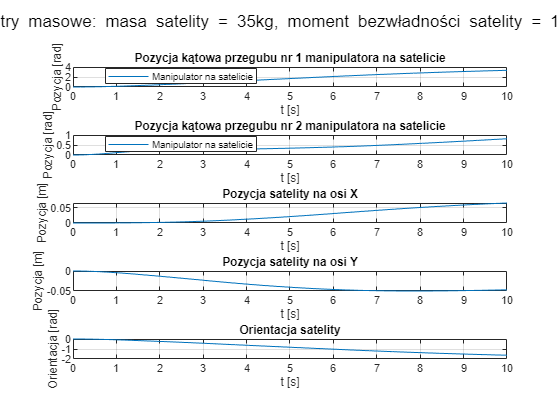

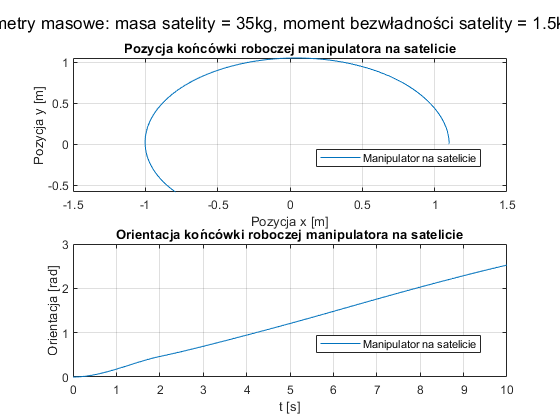

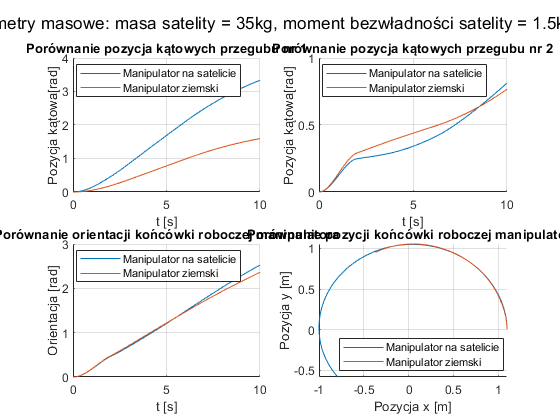

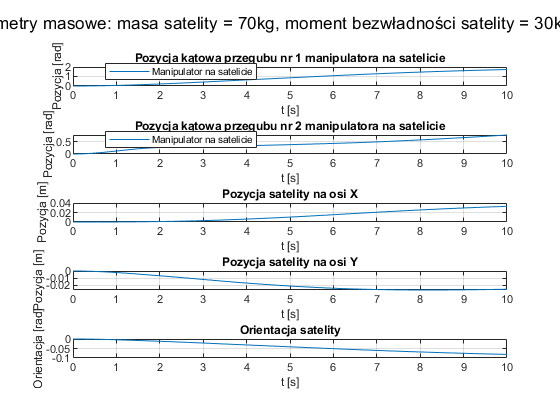

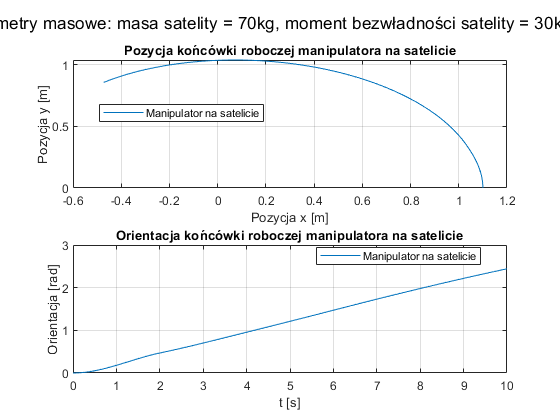

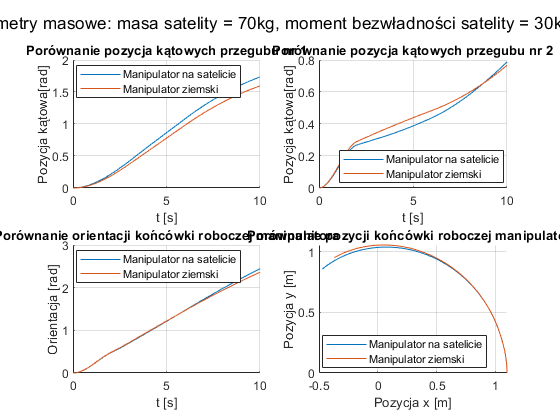

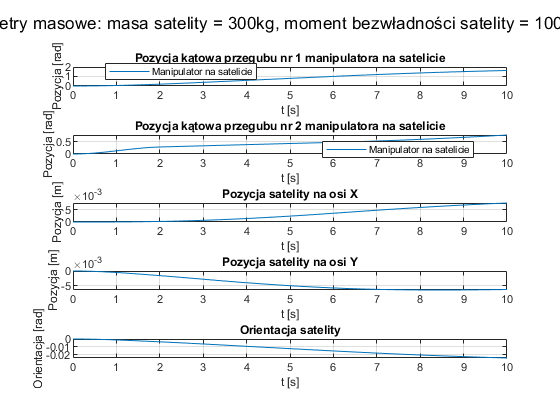

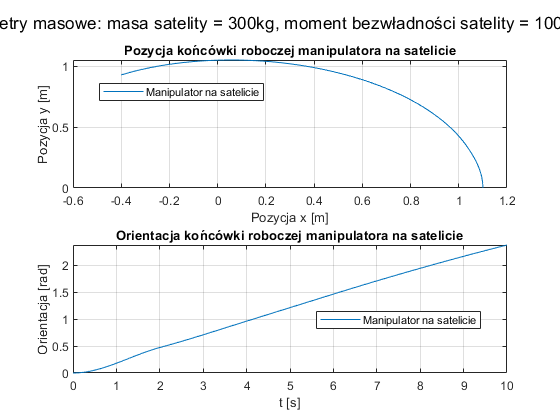

Elapsed time is 35.483565 seconds.


p1 = 0;
p2 = 0;
m1 = 2.5;
m2 = 1.5;
L1 = 0.6;
L2 = 0.5;
a1 = L1/2;
a2 = L2/2;
I0 = 1.5;
I1 = (1/12) * m1 * L1^2;
I2 = (1/12) * m2 * L2^2;

for index = 1:1:3
    m0 = [35, 70, 300];
    I0 = [1.5, 30, 100];
    text = "Parametry masowe: masa satelity = " + num2str(m0(index)) + "kg, moment bezwładności satelity = " + num2str(I0(index)) + "kg*m^2";
    [M_matrix, C_matrix] = dynamics_matrix(p1, p2, m0(index), m1, m2, L1, L2, a1, a2, I0(index), I1, I2);
    
    F_x = zeros(1, length(u));
    F_y = zeros(1, length(u));
    T_0 = zeros(1, length(u));
    Q = [F_x; F_y; T_0; u];
    h = 0.01;
    
    q0 = [0; 0; 0; 0; 0];
    dq0 = [0; 0; 0; 0; 0];
    
    [q_space, dq_space] = ode4(Q, q0, dq0, C_matrix, M_matrix, h);
    
    figure
    sgtitle(text)
    subplot(5, 1, 1)
    plot(t_1, q_space(4, :))
    legend("Manipulator na satelicie", "Location","best")
    title('Pozycja kątowa przegubu nr 1 manipulatora na satelicie')
    xlabel('t [s]'); ylabel('Pozycja [rad]')
    grid on; axis auto
    
    subplot(5, 1, 2)
    plot(t_1, q_space(5, :))
    legend("Manipulator na satelicie", "Location","best")
    title('Pozycja kątowa przegubu nr 2 manipulatora na satelicie')
    xlabel('t [s]'); ylabel('Pozycja [rad]')
    grid on; axis auto

    subplot(5, 1, 3)
    plot(t_1, q_space(1, :))
    title('Pozycja satelity na osi X')
    xlabel('t [s]'); ylabel('Pozycja [m]')
    grid on; axis auto
    
    subplot(5, 1, 4)
    plot(t_1, q_space(2, :))
    title('Pozycja satelity na osi Y')
    xlabel('t [s]'); ylabel('Pozycja [m]')
    grid on; axis auto
    
    subplot(5, 1, 5)
    plot(t_1, q_space(3, :))
    title('Orientacja satelity')
    xlabel('t [s]'); ylabel('Orientacja [rad]')
    grid on; axis auto
    
    %%% Pozycja i orientacja końcówki manipulatora na satelicie
    [Pee_space, Psiee_space] = direct_2DoF_space([q_space(4, :); q_space(5, :)]', q_space(1, :)', ...
        q_space(2, :)', q_space(3, :)', L1, L2);
    
    figure
    sgtitle(text)
    subplot(2, 1, 1)
    plot(Pee_space(:, 1), Pee_space(:, 2))
    legend("Manipulator na satelicie", "Location","best")
    title('Pozycja końcówki roboczej manipulatora na satelicie')
    xlabel('Pozycja x [m]'); ylabel('Pozycja y [m]')
    grid on; axis auto
    
    subplot(2, 1, 2)
    plot(t_1, Psiee_space)
    legend("Manipulator na satelicie", "Location","best")
    title('Orientacja końcówki roboczej manipulatora na satelicie')
    xlabel('t [s]'); ylabel('Orientacja [rad]')
    grid on; axis auto
    
    %%% Porównanie do ziemskiego
    q0 = [0; 0];
    dq0 = [0; 0];
    
    u = double(u);
    [q_earth, dq_earth] = ode4_earth(u, q0, dq0, L1, L2, m1, m2);
    [Pee_earth, Psiee_earth, Vee_earth, Omee_earth] = direct_2DoF_earth(q_earth', dq_earth', L1, L2);
    figure
    sgtitle(text)
    subplot(2, 2, 1)
    hold on
    plot(t_1, q_space(4, :))
    plot(t_1, q_earth(1, :))
    hold off
    legend("Manipulator na satelicie", 'Manipulator ziemski', "Location","best")
    title('Porównanie pozycja kątowych przegubu nr 1')
    xlabel('t [s]'); ylabel('Pozycja kątowa[rad]')
    grid on; axis auto
    
    subplot(2, 2, 2)
    hold on
    plot(t_1, q_space(5, :))
    plot(t_1, q_earth(2, :))
    hold off
    legend("Manipulator na satelicie", 'Manipulator ziemski', "Location","best")
    title('Porównanie pozycja kątowych przegubu nr 2')
    xlabel('t [s]'); ylabel('Pozycja kątowa[rad]')
    grid on; axis auto
    
    subplot(2, 2, 3)
    hold on
    plot(t_1, Psiee_space)
    plot(t_1, Psiee_earth)
    hold off
    legend("Manipulator na satelicie",'Manipulator ziemski', "Location","best")
    title('Porównanie orientacji końcówki roboczej manipulatora')
    xlabel('t [s]'); ylabel('Orientacja [rad]')
    grid on; axis auto
    
    subplot(2, 2, 4)
    hold on
    plot(Pee_space(:, 1), Pee_space(:, 2))
    plot(Pee_earth(:, 1), Pee_earth(:, 2))
    hold off
    legend("Manipulator na satelicie", 'Manipulator ziemski', "Location","best")
    title('Porównanie pozycji końcówki roboczej manipulatora')
    xlabel('Pozycja x [m]'); ylabel('Pozycja y [m]')
    grid on; axis auto
end

function [M_matrix, C_matrix] = dynamics_matrix(p1, p2, m0, m1, m2, L1, L2, a1, a2, I0, I1, I2)

    % syms p1  % manipulator mounting point in x axis
    % syms p2  % manipulator mounting point in y axis
    % syms m0  % the mass of the satellite
    % syms m1  % the mass of the first kinematic pair
    % syms m2  % the mass of the second kinematic pair
    % syms a1  % center of mass of the first link L1/2
    % syms a2  % center of mass of the second link L2/2
    % syms L1  % the length of the first link
    % syms L2  % the length of the second link
    % syms I0  % Satellite moment of inertia
    % syms I1  % Moment of inertia of the first kinematic pair 1/12 mL^2
    % syms I2  % Moment of inertia of the second kinematic pair


    syms x1  % x-positon of the satellite's center of mass [m]
    syms x2  % y-positon of the satellite's center of mass [m]
    syms x3  % satellite orientation [rad] 
    syms x4  % angular position of the first joint [rad]
    syms x5  % angular position of the second joint [rad]
    syms x6  % the first derivative of x1 [m/sec]
    syms x7  % the first derivative of x2 [m/sec]
    syms x8  % the first derivative of x3 [rad/sec]
    syms x9 % the first derivative of x4 [rad/sec]
    syms x10 % the first derivative of x5 [rad/sec]
    
    % Base (Satellite)
    J0v = [1 0 0 0 0 ;
           0 1 0 0 0 ];
    J0vt = J0v';
    J0w = [0 0 1 0 0 ];
    J0wt = J0w';
    
    % First link
    var1 = - p1*sin(x3) -p2*cos(x3) - a1*sin(x3+x4);
    var2 = -a1*sin(x3+x4);
    var3 = -p2*sin(x3) + p1*cos(x3)+a1*cos(x4+x3);
    var4 = a1*cos(x4+x3);
    J1v = [1 0  var1  var2 0 ;
           0 1  var3  var4 0 ];
    J1vt = J1v';  
    J1w = [0 0 1 1 0];
    J1wt = J1w';
    
    % Second link
    var5 = -p2*cos(x3) - L1*sin(x4+x3) - p1*sin(x3) - a2*sin(x4+x5+x3);
    var6 = -L1*sin(x4+x3) - a2*sin(x4+x5+x3);
    var7 = -a2*sin(x4+x5+x3);
    var8 = -p2*sin(x3) + a2*cos(x4+x5+x3) + L1*cos(x4+x3)+p1*cos(x3);
    var9 =  a2*cos(x4+x5+x3) + L1*cos(x4+x3);
    var10 = a2*cos(x4+x5+x3);
    J2v = [1 0   var5 var6  var7 ;
           0 1   var8 var9 var10 ];   
    J2vt = J2v';     
    J2w = [0 0 1 1 1 ];
    J2wt = J2w';
    
    % M matrix
    
    Tv = m0*J0vt*J0v +  m1*J1vt*J1v +  m2*J2vt*J2v;
    Tw = J0wt*I0*J0w +  J1wt*I1*J1w +  J2wt*I2*J2w;
    M  = Tv+Tw;
    
    % C matrix
    
    Qdot = [x6; x7; x8; x9; x10];
    Qdott =[x6 x7 x8 x9 x10 ];
    Q = [x1; x2; x3; x4; x5];
    
    for i=1:1:size(Qdot,1)
        for j=1:1:size(Qdot,1)
            sum = 0;
            for k=1:1:size(Qdot,1)
               sum = sum + diff(M(i,j),Q(k))*Qdot(k);
            end
            N1(i,j)=sum;
        end
    end
    for i=1:1:size(Qdot,1)
        for j=1:1:size(Qdot,1)
            for k=1:1:size(Qdot,1)     
              P(j,k) = diff(M(j,k),Q(i));
            end
        end
        N2(i,1) = Qdott*P*Qdot;
        clear P;
    end
    
    C = N1*Qdot - 0.5*N2;
    
    M_matrix = matlabFunction(M);
    C_matrix = matlabFunction(C);
end


function [q, dq] = ode4(Q, q_0, dq_0, C_handle, M_handle, h)
    

    q(:, 1) = q_0;
    dq(:, 1) = dq_0;
    
    for i = 1:1:length(Q)-1
        

        M = M_handle(q(3, i), q(4, i), q(5, i));
        C = C_handle(q(3, i), q(4, i), q(5, i), dq(1, i), dq(2, i), dq(3, i), dq(4, i), dq(5, i));

        K_11 = h .* dq(:, i);
        K_12 = h .* (inv(M) * (Q(:, i) - C));
        
        K_21 = h .* (dq(:, i) + K_11/2);
        k_12_dq = dq(:, i) + (K_12/2);
        C_22 = C_handle(q(3, i), q(4, i), q(5, i), k_12_dq(1), k_12_dq(2), k_12_dq(3), k_12_dq(4), k_12_dq(5));
        K_22 = h .* (inv(M) * (Q(:, i) - C_22));
        
        K_31 = h .* (dq(:, i) + K_21/2);
        k_22_dq = dq(:, i) + (K_22/2);
        C_32 = C_handle(q(3, i), q(4, i), q(5, i), k_22_dq(1), k_22_dq(2), k_22_dq(3), k_22_dq(4), k_22_dq(5));
        K_32 = h .* (inv(M) * (Q(:, i) - C_32));
        
        K_41 = h .* (dq(:, i) + K_31);
        k_32_dq = dq(:, i) + (K_32);
        C_42 = C_handle(q(3, i), q(4, i), q(5, i), k_32_dq(1), k_32_dq(2), k_32_dq(3), k_32_dq(4), k_32_dq(5));
        K_42 = h .* (inv(M) * (Q(:, i) - C_42));
        
        K_1 = (1/6) * (K_11 + 2*K_21 + 2*K_31 + K_41);
        K_2 = (1/6) * (K_12 + 2*K_22 + 2*K_32 + K_42);

        q(:, i + 1) = q(:,i) + K_1;
        dq(:, i + 1) = dq(:,i) + K_2;
    end

end

function [q, dq] = ode4_earth(u, q_0, dq_0, L1, L2, m1, m2)
    
    h = 0.01;
    q(:, 1) = q_0;
    dq(:, 1) = dq_0;

    
    for i = 1:1:length(u)-1
    
        M = [(((1/3) * m1) + m2) * L1^2 + ((1/3) * m2 * L2^2) + (m2 * L1 * L2 * cos(q(2, i))), ...
        ((1/3) * m2 * L2^2) + ((1/2) * m2 * L1 * L2 * cos(q(2, i))); ...
        ((1/3) * m2 * L2^2) + ((1/2) * m2 * L1 * L2 * cos(q(2, i))), ...
        ((1/3) * m2 * L2^2)];
   
        C = [0, (-m2 * L1 * L2 * (dq(1, i) + (1/2) * dq(2, i)) * sin(q(2, i))); ...
        ((1/2) * m2 * L1 * L2 * dq(1, i) * sin(q(2, i))), 0];
   
        K_11 = h .* dq(:, i);
        K_12 = h .* inv(M) * (u(:, i) - C*dq(:, i));
        K_21 = h .* (dq(:, i) + K_11/2);
        K_22 = h .* (inv(M) * (u(:, i) - C*(dq(:, i) + K_12/2)));
        K_31 = h .* (dq(:, i) + K_21/2);
        K_32 = h .* (inv(M) * (u(:, i) - C*(dq(:, i) + K_22/2)));
        K_41 = h .* (dq(:, i)+ K_31);
        K_42 = h .* (inv(M) * (u(:, i) - C*(dq(:, i) + K_32)));

        K_1 = (1/6) * (K_11 + 2*K_21 + 2*K_31 + K_41);
        K_2 = (1/6) * (K_12 + 2*K_22 + 2*K_32 + K_42);

        q(:, i + 1) = q(:,i) + K_1;
        dq(:, i + 1) = dq(:,i) + K_2;
    end
end


function [u] = dynamics_model(q1, q2, dq1, dq2, ddq1, ddq2, m1, m2, L1, L2)
   
    n = length(q1);
    for i=1:n
        A = [(((1/3) * m1) + m2) * L1^2 + ((1/3) * m2 * L2^2) + (m2 * L1 * L2 * cos(q2(i))), ...
       ((1/3) * m2 * L2^2) + ((1/2) * m2 * L1 * L2 * cos(q2(i))); ...
       ((1/3) * m2 * L2^2) + ((1/2) * m2 * L1 * L2 * cos(q2(i))), ...
       ((1/3) * m2 * L2^2)];
   
        B = [ddq1(i); ddq2(i)];
   
        C = [0, (-m2 * L1 * L2 * (dq1(i) + (1/2) * dq2(i)) * sin(q2(i))); ...
       ((1/2) * m2 * L1 * L2 * dq1(i) * sin(q2(i))), 0];
   
        D = [dq1(i); dq2(i)];
    
        u(:, i) = A*B + C*D;
    
    end
end

function [q,dq,ddq, t] = Trajectory_Generation(solved, q_p_in,dq_p_in,q_k_in,dq_k_in,Tk_in,Ta_in,Tb_in,dt_in,V_in)
    syms q_p q_k v
    syms t_a t_c t_k t_b
    syms dq_k dq_p
    temp = struct2cell(solved);
    val = subs(temp,{q_p, dq_p, q_k, dq_k, t_k, t_a, t_b, v},{q_p_in dq_p_in q_k_in dq_k_in Tk_in Ta_in Tb_in V_in});
    t1 = 0:dt_in:Ta_in;
    q_1 = val(1) + val(2) * t1 + val(3) * (t1).^2 + val(4) * (t1).^3;
    d_q1 = val(2) + 2*val(3)*t1 + 3*val(4) * (t1).^2;
    dd_q1 = 2*val(3) + 6*val(4)*t1;
    
    t2 = Ta_in:dt_in:(Tk_in - Tb_in);
    q_2 = val(5) + val(6) * t2;
    d_q2 = val(6) + zeros(1, length(t2));
    dd_q2 = zeros(1, length(t2));
    
    t3 = (Tk_in - Tb_in):dt_in:Tk_in;
    q_3 = val(7) + val(8) * t3 + val(9) * (t3).^2 + val(10) * (t3).^3;
    d_q3 = val(8) + 2*val(9)*t3 + 3*val(10) * (t3).^2;
    dd_q3 = 2*val(9) + 6*val(10)*t3;

    t = [0:dt_in:Tk_in];
    q = [q_1(1:end-1), q_2(1:end-1), q_3];
    dq = [d_q1(1:end-1), d_q2(1:end-1), d_q3];
    ddq = [dd_q1(1:end-1), dd_q2(1:end-1), dd_q3];
end

function [Pee, Psiee, Vee, Omee] = direct_2DoF_earth(q, dq, L1, L2)

%   q – dwuelementowy wektor zawierający pozycje kątowe przegubów [rad]
%   dq – dwuelementowy wektor zawierający prędkości kątowe przegubów[rad/s].
%   L1, L2 – długości członów manipulatora [m]
%   Pee – dwuelementowy wektor zawierający składową X i składową Y pozycji członu roboczego [m].
%   Psiee – orientacja członu roboczego [rad].
%   Vee – dwuelementowy wektor zawierający prędkość liniową członu roboczego [m/s]
%   Omee – prędkość kątowa członu roboczego [rad/s].

    Pee = [cos(q(:, 1)) .* L1 + cos(q(:,1) + q(:,2)) .* L2, sin(q(:,1)) .* L1 + sin(q(:,1) + q(:,2)) .* L2];
    Psiee = q(:,1) + q(:,2);
    Vee = [-L1 .* sin(q(:,1)) .* dq(:,1) - L2 .* sin(q(:,1)+q(:,2)).*(dq(:,1)+dq(:,2)), ...
        L1 .* cos(q(:,1)) .* dq(:,1) + L2 .* cos(q(:,1) + q(:,2)) .* (dq(:,1) + dq(:,2))];
    Omee = dq(:,1) + dq(:,2);
end

function [Pee, Psiee] = direct_2DoF_space(q, x_s, y_s, q_s, L1, L2)

%   q – dwuelementowy wektor zawierający pozycje kątowe przegubów [rad]
%   dq – dwuelementowy wektor zawierający prędkości kątowe przegubów[rad/s].
%   q_s - orientacja satelity [rad]
%   x_s, y_s - składowa X i składowa Y pozycji satelity [m] 
%   L1, L2 – długości członów manipulatora [m]
%   Pee – dwuelementowy wektor zawierający składową X i składową Y pozycji członu roboczego [m].
%   Psiee – orientacja członu roboczego [rad].
%   Vee – dwuelementowy wektor zawierający prędkość liniową członu roboczego [m/s]
%   Omee – prędkość kątowa członu roboczego [rad/s].

    Pee = [cos(q(:, 1)) .* L1 + cos(q(:,1) + q(:,2)) .* L2 + x_s, sin(q(:,1)) .* L1 + sin(q(:,1) + q(:,2)) .* L2 + y_s];
    Psiee = q(:,1) + q(:,2) + q_s;
end